clear; close all; clc;
clear all

old0pwd=pwd;

% cd ..
oldpwd=pwd;  %目前目錄路徑名
cd(strcat(oldpwd,'\羅森實測結果(磁力觀測數據)'));     % 放置地震速報站觀測的結果

%  設定這個 1

% IMU_OBS = load('2.txt'); % 沒有轉很多 效果不好??? 姿態要加強
% IMU_OBS = load('3.txt'); 
% IMU_OBS = load('4.txt'); % 
% IMU_OBS = load('5.txt'); % 沒有轉很多  
% IMU_OBS = load('6.txt'); % 效果不好  %erro??
% IMU_OBS = load('7.txt'); %  效果不好  %erro
% IMU_OBS = load('7(5 26).txt'); 
% IMU_OBS = load('8.txt'); % 很奇怪
% IMU_OBS = load('10.txt'); %  my add
% IMU_OBS = load('11.txt'); %  效果不錯   %erro y用 1,-1 ok
% IMU_OBS = load('13.txt');  % 擬合效果不好  %erro to weak
% IMU_OBS = load('13(5 26).txt'); %  但姿態有些不對
% IMU_OBS = load('16.txt'); %
% IMU_OBS = load('17.txt'); % 
% IMU_OBS = load('19.txt'); % 中間磁鐵有暫停
% IMU_OBS = load('20.txt'); %  算得很奇怪
% IMU_OBS = load('21.txt'); %  但姿態有些不對
% IMU_OBS = load('24-1.txt'); % 只有單個磁鐵有閃
% IMU_OBS = load('27.txt'); % 不理想
% IMU_OBS = load('29.txt'); % 

% IMU_OBS = load('31.txt'); % 
% IMU_OBS = load('33.txt'); % 
% IMU_OBS = load('35.txt'); % 
IMU_OBS = load('36.txt'); % 

cd(strcat(old0pwd));

Samping_rate=385; % IMU取樣率 Hz
dt=1/Samping_rate;  % IMU取樣週期 秒
[N,a2]=size(IMU_OBS); % N 為資料點數

IMU_OBS(:,2:3)=-1*IMU_OBS(:,2:3); % 方向校正
IMU_OBS(:,5:6)=-1*IMU_OBS(:,5:6); % 方向校正
%IMU_OBS(:,11:12)=-1*IMU_OBS(:,11:12); % 方向校正

IMU_run1=IMU_OBS;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 校正數據
fitdata=xlsread('fit data\data_corr_16475_5_25_IP.xlsx');
Ba=fitdata(1:3,1);Ta=fitdata(1:3,2:4);Ka=fitdata(1:3,5:7);
Bg=fitdata(5:7,1);Tg=fitdata(5:7,2:4);Kg=fitdata(5:7,5:7);
Bm=fitdata(9:11,1);Tm2a=fitdata(9:11,2:4);
Bm_2=fitdata(13:15,1);Tm2a_2=fitdata(13:15,2:4);

[a1 a2]=size(IMU_run1);
data_corr=zeros(a1,a2);
data_corr(:,1)=IMU_run1(:,1);
for i=1:a1   %校正數據
    %data_corr(i,2:4)=(Ta*Ka*(IMU_run1(i,2:4)'+Ba))';
    %data_corr(i,5:7)=(Tg*Kg*(IMU_run1(i,5:7)'+Bg))';
    %data_corr(i,8:10)=(Tm2a*(IMU_run1(i,8:10)'+Bm))';
    %data_corr(i,11:13)=(Tm2a_2*(IMU_run1(i,11:13)'+Bm_2))';
end
data_corr(:,8:9)=    IMU_run1(:,8:9);
data_corr(:,10)=   -1*IMU_run1(:,10);
data_corr(:,11:12)=-1*IMU_run1(:,11:12);
data_corr(:,13)  = -1*IMU_run1(:,13);

%IMU_run1(:,8:13)=data_corr(:,8:13)*0.01;
IMU_run1(:,8:13)=data_corr(:,8:13)*0.01;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%

time = IMU_run1(:,1);
Mag_2=IMU_run1(:,8:10); % 後面磁力儀
Mag_1=IMU_run1(:,11:13); % 前面磁力儀


plot(Mag_2(:,1) +0.75/100);
hold on
plot(Mag_1(:,1));
legend('後面磁力儀_X','前面磁力儀_X');
disp("用這個圖手動設定Mag_obs_T0、Mag_obs_T1與Mag_peak_at")

用這個圖手動設定Mag_obs_T0、Mag_obs_T1與Mag_peak_at


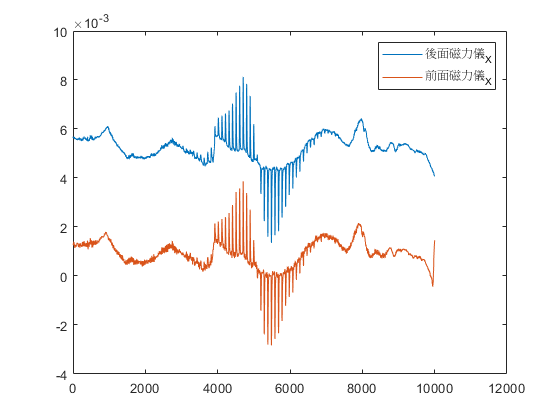

hold off

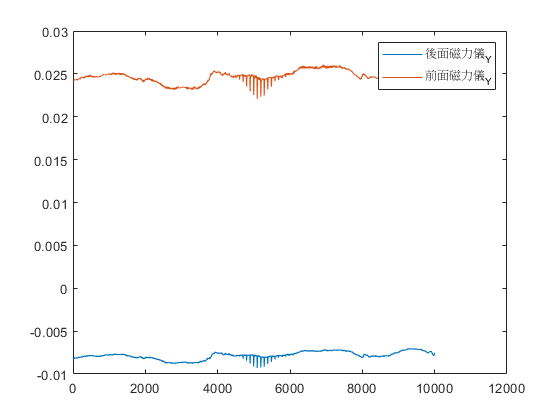


plot(Mag_2(:,2));
hold on
plot(Mag_1(:,2));
legend('後面磁力儀_Y','前面磁力儀_Y');
hold off

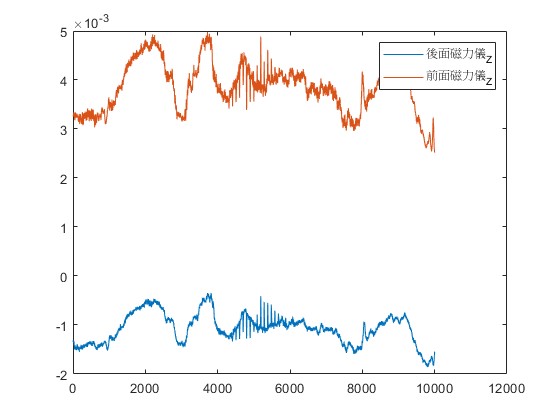


plot(Mag_2(:,3));
hold on
plot(Mag_1(:,3));
legend('後面磁力儀_Z','前面磁力儀_Z');
hold off


plot(time(:,1)-time(1,1),Mag_2(:,1))% 8~10為磁力
hold on
plot(time(:,1)-time(1,1),Mag_2(:,2))
hold on
plot(time(:,1)-time(1,1),Mag_2(:,3))
xlabel('時間(秒)', 'FontSize',14); % X座標軸
ylabel('磁力觀測值(高斯)', 'FontSize',14); % Y座標軸
legend('M_X_b(X_b方向磁力分量)','M_Y_b(Y_b方向磁力分量)','M_Z_b(Z_b方向磁力分量)');
disp("後面磁力儀")

後面磁力儀


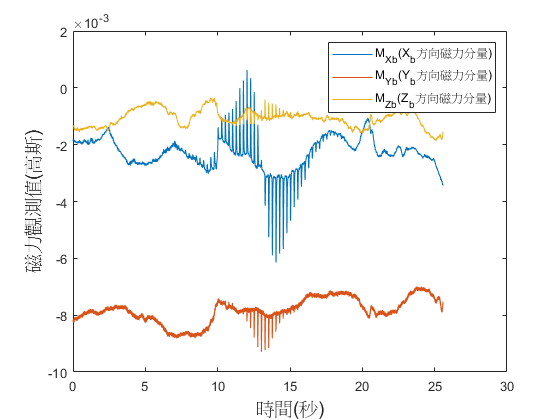

hold off


plot(time(:,1)-time(1,1),Mag_1(:,1))% 11~13為磁力
hold on
plot(time(:,1)-time(1,1),Mag_1(:,2))
hold on
plot(time(:,1)-time(1,1),Mag_1(:,3))
xlabel('時間(秒)', 'FontSize',14); % X座標軸
ylabel('磁力觀測值(高斯)', 'FontSize',14); % Y座標軸
legend('M_X_b(X_b方向磁力分量)','M_Y_b(Y_b方向磁力分量)','M_Z_b(Z_b方向磁力分量)');
disp("前面磁力儀")

前面磁力儀


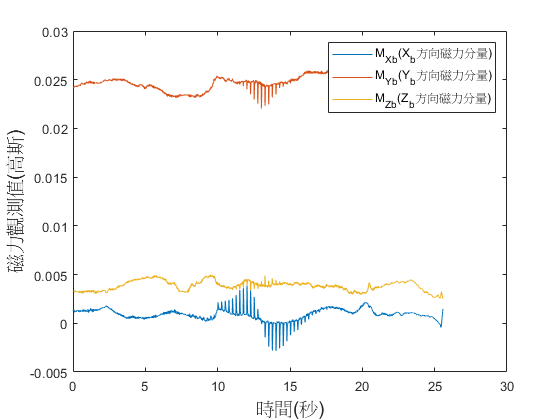

hold off

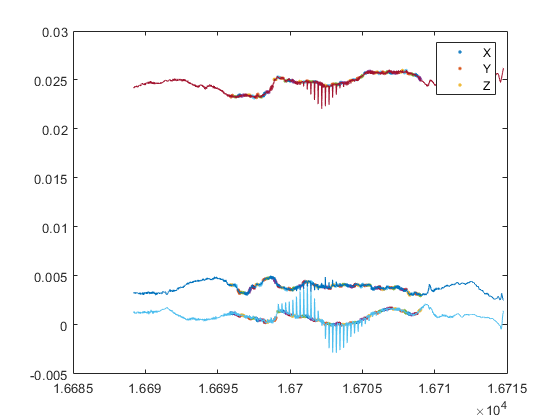

Mag_cycle=0.25; % 每秒閃4次
dt_0_1=0.035 +0.005;
dt_1_2=0.069 +0.005;

%  設定這個 2
% 
% Mag_obs_T0=380; % 須設定 '2.txt'
% Mag_obs_T1=9504; % 須設定 '2.txt'
% Mag_peak_at=4631; % 須設定 '2.txt'

% Mag_obs_T0=2530; % 須設定 '3.txt'
% Mag_obs_T1=7722; % 須設定 '3.txt'
% Mag_peak_at=4490; % 須設定 '3.txt'

% Mag_obs_T0=2000; % 須設定 '4.txt'
% Mag_obs_T1=8000; % 須設定 '4.txt'
% Mag_peak_at=4788; % 須設定 '4.txt'

% Mag_obs_T0=1319; % 須設定 '5.txt'
% Mag_obs_T1=8115; % 須設定 '5.txt'
% Mag_peak_at=5392; % 須設定 '5.txt'

% Mag_obs_T0=2029; % 須設定 '6.txt'
% Mag_obs_T1=8194; % 須設定 '6.txt'
% Mag_peak_at=5689; % 須設定 '6.txt'

% Mag_obs_T0=2518; % 須設定 '7.txt'  
% Mag_obs_T1=8512; % 須設定 '7.txt'
% Mag_peak_at=5814; % 須設定'7.txt'

% Mag_obs_T0=2663; % 須設定 '7(5 26).txt'
% Mag_obs_T1=7855; % 須設定 '7(5 26).txt'
% Mag_peak_at=5718; % 須設定'7(5 26).txt'
% 
% Mag_obs_T0=2398; % 須設定 '8.txt'
% Mag_obs_T1=7677; % 須設定 '8.txt'
% Mag_peak_at=5386; % 須設定'8.txt'

% Mag_obs_T0=1976; % 須設定 '10.txt'  %my add
% Mag_obs_T1=7860; % 須設定 '10.txt'
% Mag_peak_at=5450; % 須設定'10.txt'

% Mag_obs_T0=1976; % 須設定 '11.txt'
% Mag_obs_T1=7860; % 須設定 '11.txt'
% Mag_peak_at=5441; % 須設定'11.txt'

% Mag_obs_T0=1250; % 須設定 '13.txt'
% Mag_obs_T1=7860; % 須設定 '13.txt'
% Mag_peak_at=5574; % 須設定'13.txt'
% % 
% Mag_obs_T0=2291; % 須設定 '13(5 26).txt'
% Mag_obs_T1=8210; % 須設定 '13(5 26).txt'
% Mag_peak_at=5486; % 須設定'13(5 26).txt'

% Mag_obs_T0=1849; % 須設定 '16.txt'
% Mag_obs_T1=7696; % 須設定 '16.txt'
% Mag_peak_at=4529; % 須設定'16.txt'

% Mag_obs_T0=1723; % 須設定 '17.txt'
% Mag_obs_T1=7743; % 須設定 '17.txt'
% Mag_peak_at=4270; % 須設定'17.txt'
% 
% Mag_obs_T0=2258; % 須設定 '19.txt'
% Mag_obs_T1=8104; % 須設定 '19.txt'
% Mag_peak_at=5671; % 須設定'19.txt'

% Mag_obs_T0=2272; % 須設定 '20.txt'
% Mag_obs_T1=7169; % 須設定 '20.txt'
% Mag_peak_at=5292; % 須設定'20.txt'

% Mag_obs_T0=1911; % 須設定 '21.txt'
% Mag_obs_T1=7020; % 須設定 '21.txt'
% Mag_peak_at=4442; % 須設定'21.txt'

% Mag_obs_T0=2388; % 須設定 '24-1.txt'
% Mag_obs_T1=7934; % 須設定 '24-1.txt'
% Mag_peak_at=4457; % 須設定'24-1.txt'

% Mag_obs_T0=2039; % 須設定 '27.txt'
% Mag_obs_T1=8194; % 須設定 '27.txt'
% Mag_peak_at=5405; % 須設定'27.txt'
% % 
% Mag_obs_T0=2383; % 須設定 '29.txt'
% Mag_obs_T1=7697; % 須設定 '29.txt'
% Mag_peak_at=5034; % 須設定'29.txt'

% Mag_obs_T0=2237; % 須設定 '31.txt' 
% Mag_obs_T1=7972; % 須設定 '31.txt'
% Mag_peak_at=4600; % 須設定'31.txt'

% Mag_obs_T0=2620; % 須設定 '33.txt'
% Mag_obs_T1=7837; % 須設定 '33.txt'
% Mag_peak_at=4809; % 須設定'33.txt'

% Mag_obs_T0=2397; % 須設定 '35.txt' 
% Mag_obs_T1=7613; % 須設定 '35.txt'
% Mag_peak_at=4529; % 須設定'35.txt'

Mag_obs_T0=2664; % 須設定 '36.txt'
Mag_obs_T1=7690; % 須設定 '36.txt'
Mag_peak_at=5487; % 須設定'36.txt'

% V_test= 1.015785861; %2 % my add
% V_test= 1.170473571; %3
% V_test= 1.171027249; %4
% V_test= 1.262733447; %5
% V_test= 1.278470913; %6 %erro ??
% V_test= 1.231576822; %7 %erro 
% V_test= 1.185789276; %7 26
% V_test= 1.14872364; %8
% V_test= 1.188470897; %10(11 25)
% V_test= 1.415598291; %11 26   %erro yz似合 y改1、-1 ok
% V_test= 1.204935415; %13 %erro weak
% V_test= 1.340247308; %13 26
% V_test= 1.306818182; %16 %erro yz似合 y改1、-1 ok
% V_test= 1.305236077; %17
% V_test= 1.257012623; %19
% V_test= 1.335907945; %20
% V_test= 1.340996169; %21
% V_test= 1.286764706; %24-1 %%erro 待修正
% V_test= 1.150468384; %27
% V_test= 0.975506757; %29
% V_test= 1.441647597; %31
% V_test= 1.296172675; %33
% V_test= 1.238111413; %35
V_test= 1.515989541; %36

%%%%%%%%%%%%%%%%%%%%%%%%%%

NO_cycl_0_1=round((time(Mag_peak_at,1)-time(Mag_obs_T0,1))/Mag_cycle);
NO_cycl_1_2=round((time(Mag_obs_T1,1)-time(Mag_peak_at,1))/Mag_cycle);

T_peak_at=[time(Mag_peak_at,1)-Mag_cycle*NO_cycl_0_1:Mag_cycle:time(Mag_peak_at,1)+Mag_cycle*NO_cycl_1_2]';
T_take_off=T_peak_at-dt_0_1;
T_landing=T_peak_at+dt_1_2;

NO_cycl=NO_cycl_0_1+NO_cycl_1_2+1;

%%%%%%%%%%%%%%%%%%%%%%%%%%
M_1_pulse=zeros(NO_cycl,3);
T_1_pulse=zeros(NO_cycl,1);
T_temp_pulse=zeros(1,3);
for i=1:NO_cycl
    for j=1:3
        [M_temp,T_temp_1]=min(abs(time(:,1)-T_take_off(i)));
        [M_temp,T_temp_2]=min(abs(time(:,1)-T_landing(i)));

        Mag_i=(Mag_1(T_temp_2,j)-Mag_1(T_temp_1,j)).*(time(T_temp_1:T_temp_2,1)-time(T_temp_1,1)).....
            ./(time(T_temp_2,1)-time(T_temp_1,1))+Mag_1(T_temp_1,j);

        [M_temp,T_temp]=max(abs((Mag_1(T_temp_1:T_temp_2,j)-Mag_i)));
        M_1_pulse(i,j)=Mag_1(T_temp+T_temp_1-1,j)-Mag_i(T_temp,1); % 尖峰磁力差值

        T_temp_pulse(1,j)=T_temp+T_temp_1-1; % 時間點

        plot(time(T_temp_1:T_temp_2,1),Mag_i,'.')
        hold on
    end

    [M_temp,j_temp]=max(abs(M_1_pulse(i,:)));
    T_1_pulse(i,1)=T_temp_pulse(1,j_temp);
end

plot(time(:,1),Mag_1(:,:))
legend('X','Y','Z');
hold off

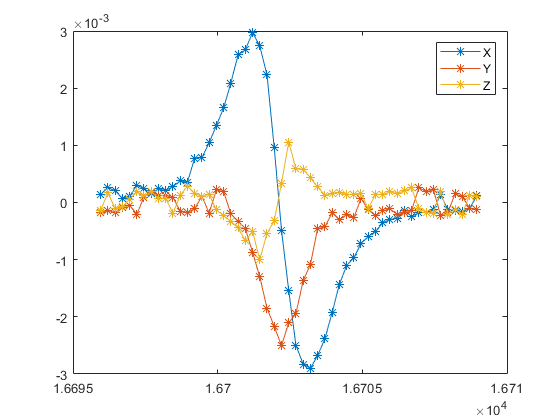


plot( T_peak_at,M_1_pulse,'-*')
legend('X','Y','Z');
hold off

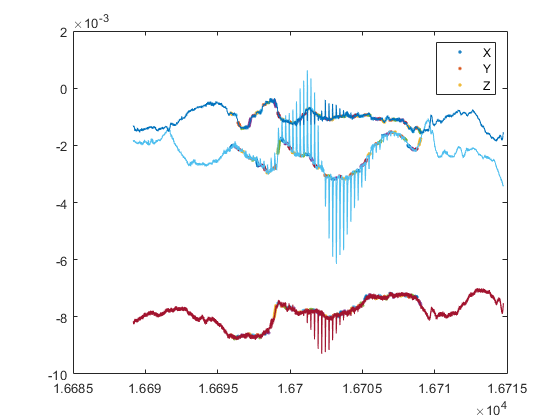

%%%%%
M_2_pulse=zeros(NO_cycl,3);
T_2_pulse=zeros(NO_cycl,1);
T_temp_pulse=zeros(1,3);
for i=1:NO_cycl
    for j=1:3
        [M_temp,T_temp_1]=min(abs(time(:,1)-T_take_off(i)));
        [M_temp,T_temp_2]=min(abs(time(:,1)-T_landing(i)));

        Mag_i=(Mag_2(T_temp_2,j)-Mag_2(T_temp_1,j)).*(time(T_temp_1:T_temp_2,1)-time(T_temp_1,1)).....
            ./(time(T_temp_2,1)-time(T_temp_1,1))+Mag_2(T_temp_1,j);

        [M_temp,T_temp]=max(abs((Mag_2(T_temp_1:T_temp_2,j)-Mag_i)));
        M_2_pulse(i,j)=Mag_2(T_temp+T_temp_1-1,j)-Mag_i(T_temp,1); % 尖峰磁力差值

        T_temp_pulse(1,j)=T_temp+T_temp_1-1; % 時間點

        plot(time(T_temp_1:T_temp_2,1),Mag_i,'.')
        hold on
    end

    [M_temp,j_temp]=max(abs(M_2_pulse(i,:)));
    T_2_pulse(i,1)=T_temp_pulse(1,j_temp);

end

plot(time(:,1),Mag_2(:,:))
legend('X','Y','Z');
hold off

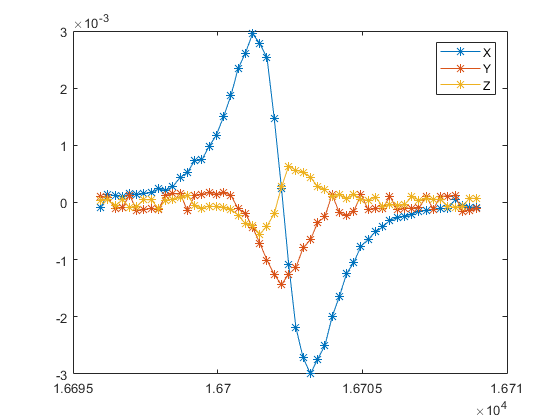


plot( T_peak_at,M_2_pulse,'-*')
legend('X','Y','Z');
hold off

%%%%%%%%%%%%%%%%%%%%%%%%%%


IMU=IMU_run1; % 載入觀測資料

Samping_rate=385; % IMU取樣率 Hz
dt=1/Samping_rate;  % IMU取樣週期 秒

[N,a2]=size(IMU); % N 為資料點數

IMU_filter=IMU;

time = IMU(:,1);

%%%% 計算時間差 (不是時間)
dt_i=zeros(N,1);
for i=2:N-1
    %dt_i(i,1)=(IMU(i+1,1)-IMU(i-1,1))/2;
    dt_i(i,1)=(IMU(i,1)-IMU(i-1,1));
end
dt_i(1,1)=dt/2; dt_i(N,1)=dt/2;

%%%%% 加速度
%n=2;
%Wn=1/100;
n=2;
%Wn=1/20;
Wn=1/10; %  用這值會有理想的水平路徑  原本這樣
%Wn=1/50;
%[b,a] = butter(n,Wn,'high'); % 高通濾波
[b,a] = butter(n,Wn,'low'); %  低通濾波
IMU_filter(:,2) = filter(b,a,IMU(:,2)); % 暫時刪除?
IMU_filter(:,3) = filter(b,a,IMU(:,3)); % 暫時刪除?
IMU_filter(:,4) = filter(b,a,IMU(:,4)); % 暫時刪除?

%IMU_filter(:,2) = IMU(:,2); % !!!!!!!!!!
%IMU_filter(:,3) = IMU(:,3); % !!!!!!!!!!
%IMU_filter(:,4) = IMU(:,4); % !!!!!!!!!!

%%%%%%%%%%%


%%%%  角速度
n=4;
%Wn=1/100; %  用這值會有理想的水平路徑  原本這樣
Wn=1/200; %
%Wn=1/5;
% n=10;
IMU_filter(:,5:7) = IMU(:,5:7);
[b,a] = butter(n,Wn,'low'); %  低通濾波
%IMU_filter(:,5) = filter(b,a,IMU(:,5));
%IMU_filter(:,6) = filter(b,a,IMU(:,6));
%IMU_filter(:,7) = filter(b,a,IMU(:,7)); %

n=2;
Wn=1/(Samping_rate*60*20);%  用這值會有理想的水平路徑  原本這樣
%Wn=1/(Samping_rate*60*5);%
[b,a] = butter(n,Wn,'high'); % 高通濾波 用這值會有理想的水平路徑  原本這樣
%IMU_filter(:,5) = filter(b,a,IMU_filter(:,5));
%IMU_filter(:,6) = filter(b,a,IMU_filter(:,6));
%IMU_filter(:,7) = filter(b,a,IMU_filter(:,7)); 



plot(IMU(:,1)-IMU(1,1),IMU(:,5))
hold on
plot(IMU(:,1)-IMU(1,1),IMU_filter(:,5))
legend('Input Data','Filtered Data')
disp("X軸角速度(濾波後)")

X軸角速度(濾波後)


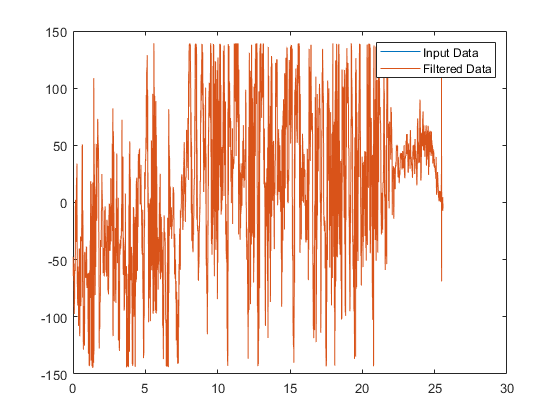

hold off


plot(IMU(:,1)-IMU(1,1),IMU(:,6))
hold on
plot(IMU(:,1)-IMU(1,1),IMU_filter(:,6))
hold on
plot(IMU(:,1)-IMU(1,1),smooth(IMU_filter(:,6),30))
legend('Input Data','Filtered GyroY','smooth')
disp("Y軸角速度(濾波後)")

Y軸角速度(濾波後)


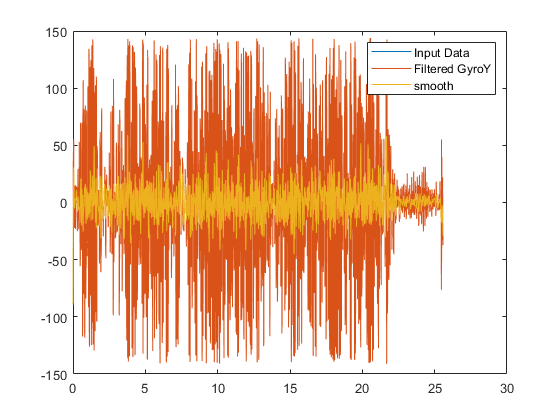

hold off


plot(IMU(:,1)-IMU(1,1),IMU(:,7))
hold on
plot(IMU(:,1)-IMU(1,1),IMU_filter(:,7))
hold on
plot(IMU(:,1)-IMU(1,1),smooth(IMU_filter(:,7),30))
legend('Input Data','Filtered GyroZ','smooth')
disp("Z軸角速度(濾波後)")

Z軸角速度(濾波後)


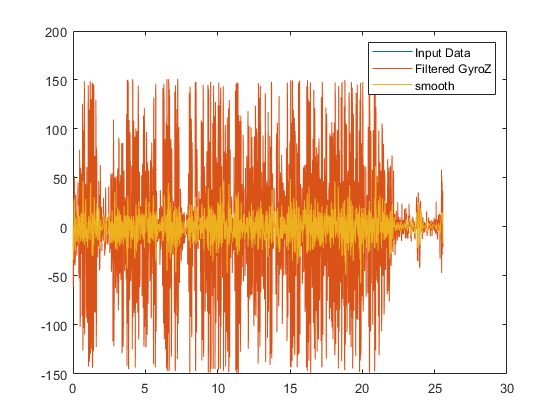

hold off


plot(IMU(:,1)-IMU(1,1),IMU_filter(:,5))
hold on
plot(IMU(:,1)-IMU(1,1),IMU_filter(:,6))
hold on
plot(IMU(:,1)-IMU(1,1),IMU_filter(:,7))
legend('角速度5','角速度6','角速度7')
disp("XYZ軸角速度(濾波後)")

XYZ軸角速度(濾波後)


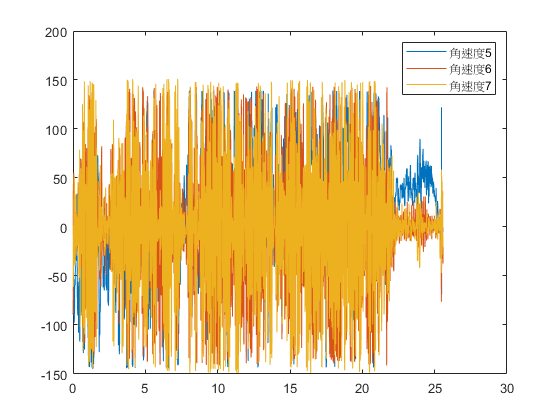

hold off

%%%%%

acc_filtered=IMU_filter(:,2:4);
gyro_filtered=IMU_filter(:,5:7);

% gyro_filtered(:,1)=gyro_filtered(:,1)*0; % 暫時這樣 !!!!!!!!!!!!!!!!!!
mean1=mean(gyro_filtered(:,1));
mean2=mean(gyro_filtered(:,2));
mean3=mean(gyro_filtered(:,3));
%gyro_filtered(:,1)=gyro_filtered(:,1)-mean1;
%gyro_filtered(:,2)=gyro_filtered(:,2)-mean2;
%gyro_filtered(:,3)=gyro_filtered(:,3)-mean3;



q=zeros(4,N);
%dis_q=zeros(4,N);
% == Initialization ==
init_a = mean(acc_filtered(1:20,1:3),1);
init_a = init_a / norm(init_a);
init_psi =  0;
init_theta = 0; %-asin(init_a(1));
init_phi = atan2(init_a(2), init_a(3));
q(:,1) = angle2quat(init_psi, init_theta, init_phi);
% == Initialization ==

phi_accelerometer=zeros(N,1);
theta_accelerometer=zeros(N,1);
psi_accelerometer=zeros(N,1);
quat_accelerometer=zeros(4,N);
theta_accelerometer_show=zeros(N,1);
for i=1:N
    acc = acc_filtered(i,:);
    acc = acc / norm(acc);
    %phi_accelerometer(i,1) =-atan2(-acc(2),acc(3));  % roll
    %theta_accelerometer(i,1) =-atan2(acc(1),sign(acc(3))*(acc(2)^2+acc(3)^2)^0.5);  % pitch
    %psi_accelerometer(i,1) =  0; %phi_accelerometer(i,1)-(Roll2-Yaw2); % 徑度
    %quat_accelerometer(:,i) = angle2quat(psi_accelerometer(i,1), theta_accelerometer(i,1), phi_accelerometer(i,1),  'ZYX' );
    phi_accelerometer(i,1) = atan2(acc(2), acc(3));
    theta_accelerometer(i,1) = -asin(acc(1));
    psi_accelerometer(i,1) =  0;
    quat_accelerometer(:,i) = angle2quat(psi_accelerometer(i,1), theta_accelerometer(i,1), phi_accelerometer(i,1));


    theta_accelerometer_show(i,1)=theta_accelerometer(i,1);
    if theta_accelerometer_show(i,1)>pi/2
        theta_accelerometer_show(i,1)=theta_accelerometer_show(i,1)-pi;
    end
    if theta_accelerometer_show(i,1)<-pi/2
        theta_accelerometer_show(i,1)=theta_accelerometer_show(i,1)+pi;
    end
end


%%% complementary filter %%%
% http://www.pieter-jan.com/node/11
% https://sites.google.com/site/myimuestimationexperience/filters/complementary-filter
Roll_complementary_filter=zeros(N,1); 
Pitch_complementary_filter=zeros(N,1);
Yaw_complementary_filter=zeros(N,1);
q_complementary_filter=zeros(4,N);
q_complementary_filter(:,1) = angle2quat(init_psi, init_theta, init_phi); % 0,0,init_phi
for i=2:N
    w=gyro_filtered(i,1:3)/180*pi; % 徑度
    w(2)=0; % 暫時測試
    w(3)=0; % 暫時測試
    
    Ow = [0     -w(1)   -w(2)    -w(3);...
        w(1)   0       w(3)    -w(2);...
        w(2)  -w(3)    0        w(1);...
        w(3)   w(2)   -w(1)     0  ];
    q_complementary_filter(:,i) = q_complementary_filter(:,i-1) + 0.5*Ow*dt_i(i,1)*q_complementary_filter(:,i-1) ;
    q_complementary_filter(:,i) = q_complementary_filter(:,i) / norm(q_complementary_filter(:,i));
    [ Yaw_gyro,Pitch_gyro,Roll_gyro ]  = quat2angle(q_complementary_filter(:,i)', 'ZYX');    
    % angle=0.98*(angle+gyrData*dt)+0.02*accData

    a_parameter=1.0; % 0.999999 用這值會靠陀螺儀計算轉角; % 須設定
    %a_parameter=0.995; % 0.995 用這值會有理想的姿態; % 須設定
    %%% Roll_complementary_filter(i,1)
    x1=Roll_gyro;
    x2=phi_accelerometer(i,1);
    x3=a_parameter*Roll_gyro+(1-a_parameter)*phi_accelerometer(i,1);

    %x3=(1)*phi_accelerometer(i,1);
    if x1>0 && x2<0
        if x1-x2>x2+2*pi-x1
            x2_temp=x2+2*pi;
            x3=a_parameter*x1+(1-a_parameter)*x2_temp;
            if x3>2*pi
                x3=x3-2*pi;
            end
        end
    end
    if x1<0 && x2>0
        if x2-x1>x1+2*pi-x2
            x2_temp=x2-2*pi;
            x3=a_parameter*x1+(1-a_parameter)*x2_temp;
            if x3<-2*pi
                x3=x3+2*pi;
            end
        end
    end
    Roll_complementary_filter(i,1)=x3;    
    
    %%% Pitch_complementary_filter(i,1)
    %a_parameter=0.999; % 0.999 用這值會有理想的水平路徑; % 須設定
    %%a_parameter=0.999999999; % 0.999  % 須設定
    %x1=Pitch_gyro;
    %x2=theta_accelerometer(i,1);
    %x3=a_parameter*Pitch_gyro+(1-a_parameter)*theta_accelerometer(i,1);
    %if x1>0 && x2<0
    %    if x1-x2>x2+2*pi-x1
    %        x2=x2+2*pi;
    %        x3=a_parameter*x1+(1-a_parameter)*x2;
    %        if x3>2*pi
    %            x3=x3-2*pi;
    %        end
    %    end
    %end
    %if x1<0 && x2>0
    %    if x2-x1>x1+2*pi-x2
    %        x2=x2-2*pi;
    %        x3=a_parameter*x1+(1-a_parameter)*x2;
    %        if x3<-2*pi
    %            x3=x3+2*pi;
    %        end
    %    end
    %end
    %Pitch_complementary_filter(i,1)=x3;
    %%%

    %q_complementary_filter(:,i) = angle2quat(0,Pitch_complementary_filter(i,1),Roll_complementary_filter(i,1),'ZYX');
    q_complementary_filter(:,i) = angle2quat(0,0,Roll_complementary_filter(i,1),'ZYX');
end
%%% complementary filter %%%





%%%%% 線性修正complementary %%%%%
Roll_complementary_filter_uncorr=Roll_complementary_filter;
[T_section_N,a2]=size(Roll_complementary_filter);
phi_acc_i=phi_accelerometer;
Roll_comp_i=Roll_complementary_filter;
for i=1:N
    if Roll_comp_i(i,1)<0 && phi_acc_i(i,1)>Roll_comp_i(i,1)+pi
        phi_acc_i(i,1)=phi_acc_i(i,1)-2*pi;
    end
    if Roll_comp_i(i,1)>0 && phi_acc_i(i,1)<Roll_comp_i(i,1)-pi
        phi_acc_i(i,1)=phi_acc_i(i,1)+2*pi;
    end
end
    p = polyfit(time,phi_acc_i-Roll_comp_i,1); % 線性回歸
    a=p(1,1);
    b=p(1,2);
    Roll_complementary_filter=a*time+b+Roll_comp_i;
%%%%%%

plot(time(:,1)-time(1,1),phi_accelerometer/pi*180,'.') % 旋轉角
hold on
plot(time(:,1)-time(1,1),Roll_complementary_filter_uncorr/pi*180,'.') % 旋轉角
hold on
plot(time(:,1)-time(1,1),Roll_complementary_filter/pi*180,'.') % 旋轉角

legend('旋轉角 from acc','旋轉角 Roll complementary uncorr','旋轉角 Roll complementary')
disp("旋轉角 存這個圖!!")

旋轉角 存這個圖!!


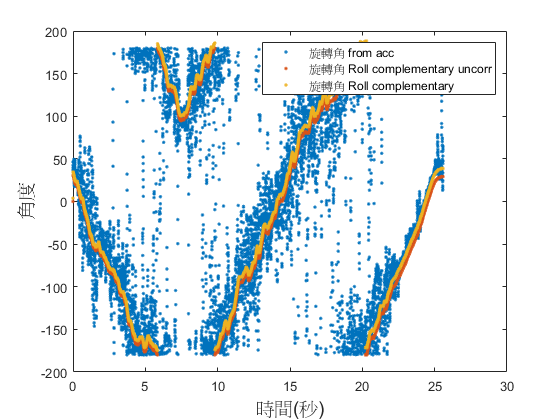

xlabel('時間(秒)', 'FontSize',14); % X座標軸
ylabel('角度', 'FontSize',14); % Y座標軸
hold off



%%%% 傾角
plot(IMU(:,1)-IMU(1,1),Pitch_complementary_filter/pi*180,'.')
disp("GLOBE傾角(濾波前)")

GLOBE傾角(濾波前)


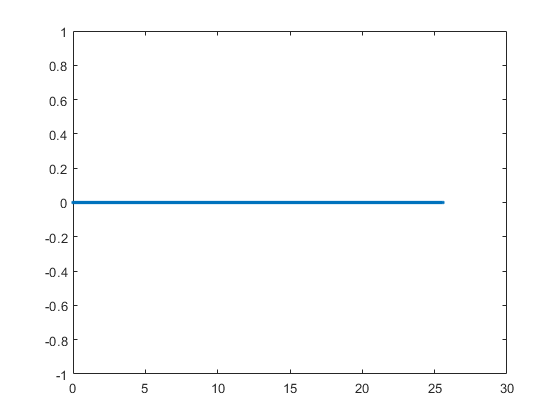

hold off



%Wn=1/Samping_rate*5.0; % 5Hz
Wn=1/Samping_rate*10.0; % 10Hz
n=2;
[b,a] = butter(n,Wn,'low'); %  低通濾波
%theta_accelerometer_show_2 = filter(b,a,theta_accelerometer_show);
theta_accelerometer_show_2 = filter(b,a,Pitch_complementary_filter);
plot(IMU(:,1)-IMU(1,1),theta_accelerometer_show_2/pi*180,'.')
hold on
Wn=1/Samping_rate*0.5;
n=2;
[b,a] = butter(n,Wn,'low'); %  低通濾波
%theta_accelerometer_show_1 = filter(b,a,theta_accelerometer_show);
theta_accelerometer_show_1 = filter(b,a,Pitch_complementary_filter);
plot(IMU(:,1)-IMU(1,1),theta_accelerometer_show_1/pi*180)
legend('傾角(低頻)','傾角(高頻)')
xlabel('水平距離(公尺)', 'FontSize',14); % X座標軸
ylabel('傾角(度)(下坡為正)', 'FontSize',14); % Y座標軸
disp("GLOBE傾角(濾波後)")

GLOBE傾角(濾波後)


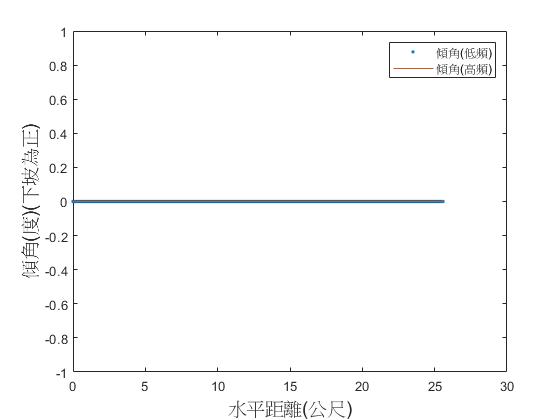

hold off


dis_Pitch=zeros(N,1);
%dis_Pitch(2:end,1)=Pitch_complementary_filter(2:end,1)-Pitch_complementary_filter(1:end-1,1);
dis_Pitch(2:end,1)=theta_accelerometer_show_2(2:end,1)-theta_accelerometer_show_2(1:end-1,1); % 直接使用濾過的theta_accelerometer
plot(IMU(:,1)-IMU(1,1),dis_Pitch/pi*180,'.')
disp("GLOBE傾角增量")

GLOBE傾角增量


hold off


Wn=1/Samping_rate*5.0;
n=5;
[b,a] = butter(n,Wn,'low'); %  低通濾波
dis_Pitch_filtered = filter(b,a,dis_Pitch);
plot(IMU(:,1)-IMU(1,1),dis_Pitch_filtered/pi*180,'.') % 5Hz低通濾波(取低頻) 使用它做後續 此Hz數越大轉折越銳利 dis_Yaw2
legend('GLOBE傾角增量低通濾波')
disp("GLOBE傾角增量低通濾波")

GLOBE傾角增量低通濾波


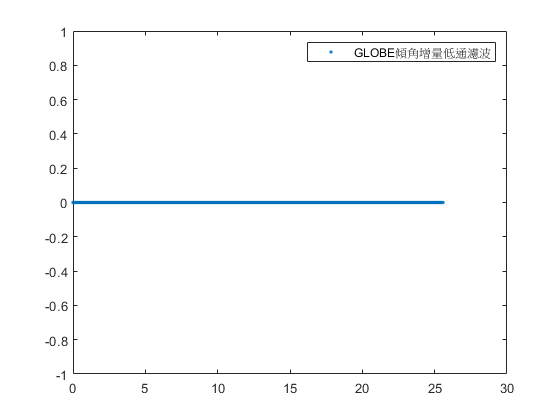

hold off



dis_Pitch_filtered = dis_Pitch; % 如果不濾波 !!!!


%Wn=1/Samping_rate*10.0;
%n=5;
%[b,a] = butter(n,Wn,'low'); %  低通濾波
%dis_Pitch_filtered = filter(b,a,dis_Pitch);
%plot(IMU(:,1)-IMU(1,1),dis_Pitch_filtered/pi*180,'.') % 5Hz低通濾波(取低頻) 使用它做後續 此Hz數越大轉折越銳利 dis_Yaw2
%legend('GLOBE傾角增量低通濾波')
%disp("GLOBE傾角增量低通濾波")
%hold off

accum_Pitch=zeros(N,1);
for i=2:N
    if abs(dis_Pitch_filtered(i,1)/pi*180)<0.025 % !!!!!!!!!!!!!!!!!!!!!!
        dis_Pitch_filtered(i,1)=0;                  % 轉角增量若太小 就直接當成直管 強制設成0 !!!!!!!!!!!!!
    end
    accum_Pitch(i,1)=accum_Pitch(i-1,1)+dis_Pitch_filtered(i,1);
end

plot(IMU(:,1)-IMU(1,1),accum_Pitch/pi*180,'.')
legend('accum_Pitch')
disp("傾角")

傾角


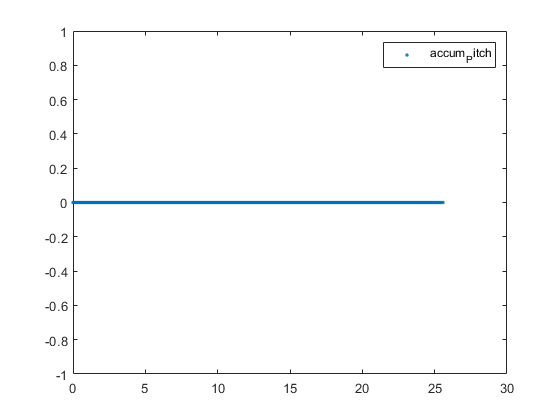

hold off

%%%%%%%




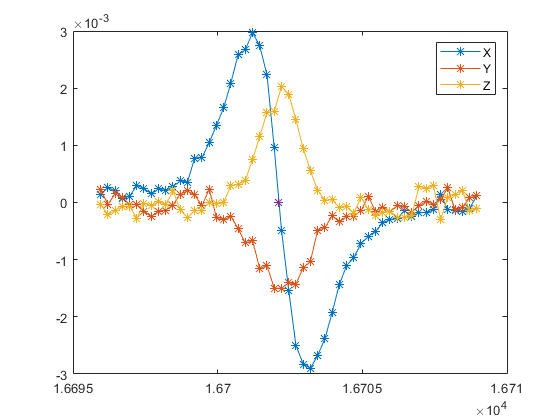

global M_pulse_globe ga_X

M_1_pulse_globe=zeros(NO_cycl,3);
M_2_pulse_globe=zeros(NO_cycl,3);

for i=1:NO_cycl

    q_complementary_for_M = angle2quat(0,0,Roll_complementary_filter(T_2_pulse(i,1),1),'ZYX'); % 注意 假設傾角為0
    dcm_quat_accelerometer = quat2dcm(q_complementary_for_M);
    G_accelerometer = dcm_quat_accelerometer' * M_1_pulse(i,:)';
    M_1_pulse_globe(i,:)=G_accelerometer';

    dcm_quat_accelerometer = quat2dcm(q_complementary_for_M);
    G_accelerometer = dcm_quat_accelerometer' * M_2_pulse(i,:)';
    M_2_pulse_globe(i,:)=G_accelerometer';
    
    %M_1_pulse_globe(i,1)=M_1_pulse(i,1);
    %%[M_1_pulse_globe(i,2),M_1_pulse_globe(i,3)] = .....
    %%    pol2cart(Roll_complementary_filter(T_1_pulse(i,1),1),(M_1_pulse(i,2)^2+M_1_pulse(i,3)^2)^0.5);
    %[M_1_pulse_globe(i,2),M_1_pulse_globe(i,3)] = .....
    %    pol2cart(-1*Roll_complementary_filter(T_1_pulse(i,1),1),(M_1_pulse(i,2)^2+M_1_pulse(i,3)^2)^0.5);
    
    %M_2_pulse_globe(i,1)=M_2_pulse(i,1);
    %%[M_2_pulse_globe(i,2),M_2_pulse_globe(i,3)] = .....
    %%    pol2cart(Roll_complementary_filter(T_2_pulse(i,1),1),(M_2_pulse(i,2)^2+M_2_pulse(i,3)^2)^0.5);
    %[M_2_pulse_globe(i,2),M_2_pulse_globe(i,3)] = .....
    %    pol2cart(-1*Roll_complementary_filter(T_2_pulse(i,1),1),(M_2_pulse(i,2)^2+M_2_pulse(i,3)^2)^0.5);
end




[a1,a2]=max(M_1_pulse_globe(:,1));
[a3,a4]=min(M_1_pulse_globe(:,1));
T_close_1=0;
for i=a2:a4-1
    if M_1_pulse_globe(i,1)*M_1_pulse_globe(i+1,1)<0
        if T_close_1>0
%             ERR
        end
        T_close_1=T_peak_at(i,1)+(T_peak_at(i+1,1)-T_peak_at(i,1))*.....
             (0-M_1_pulse_globe(i,1))/(M_1_pulse_globe(i+1,1)-M_1_pulse_globe(i,1));
    end
end
[a1,a2]=max(M_2_pulse_globe(:,1));
[a3,a4]=min(M_2_pulse_globe(:,1));
T_close_2=0;
for i=a2:a4-1
    if M_2_pulse_globe(i,1)*M_2_pulse_globe(i+1,1)<0
        if T_close_2>0
%             ERR
        end
        T_close_2=T_peak_at(i,1)+(T_peak_at(i+1,1)-T_peak_at(i,1))*.....
             (0-M_2_pulse_globe(i,1))/(M_2_pulse_globe(i+1,1)-M_2_pulse_globe(i,1));
    end
end

plot( T_peak_at,M_1_pulse_globe,'-*')
hold on
plot( T_close_1,0,'*')
legend('X','Y','Z');
hold off

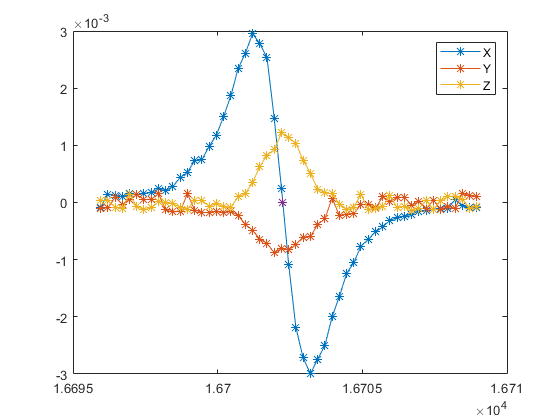


plot( T_peak_at,M_2_pulse_globe,'-*')
hold on
plot( T_close_2,0,'*')
legend('X','Y','Z');
hold off


dis_M1_M2=0.15; % 兩個磁力儀間距0.15公分
%V_test=dis_M1_M2/(T_close_2-T_close_1) 

%  設定這個 3
% V_test= 1.29617267467658  % 假設速度為 1 m/s 暫時這樣 後續須修正     須設定

ga_X=(T_peak_at-T_peak_at(1,1))*V_test;

plot( ga_X,M_1_pulse_globe,'-*')
legend('X','Y','Z');
title('磁力觀測值(Globe坐標)');  % 圖形標題
disp("存這個圖!!")

存這個圖!!


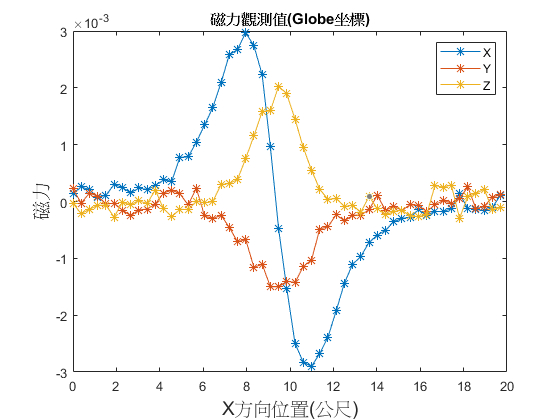

xlabel('X方向位置(公尺)', 'FontSize',14); % X座標軸
ylabel('磁力', 'FontSize',14); % Y座標軸
hold off

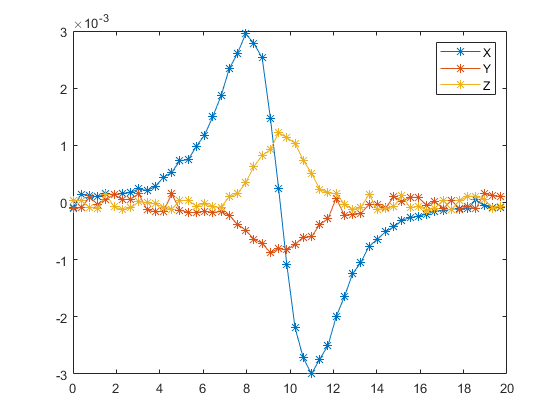


plot( ga_X,M_2_pulse_globe,'-*')
legend('X','Y','Z');
hold off


%temp=[ga_X M_1_pulse_globe];
%save RUN35.txt temp -ascii;

weeeeeeeeee

Unrecognized function or variable 'weeeeeeeeee'.

global M_pulse_globe ga_X

M_pulse_globe=M_1_pulse_globe; % 前面磁力儀

%  設定這個 4
%%%%% 執行基因演算法
Ub=[13 ;  4 ;     0 ; 2.0 ; 0.8]; % 適度調整系數上邊界 X Y Z X方向的磁力殘留係數
Lb=[7 ;  -3;  -3 ; 0.15; 0.0002]; % 適度調整系數下邊界
% Ub=[13 ;  1 ;     0 ; 2.0 ; 0.8]; % 適度調整系數上邊界 X Y Z X方向的磁力殘留係數
% Lb=[7 ;  -1;  -3 ; 0.15; 0.0002]; % 適度調整系數下邊界

%Ub=[8 ;  0 ; -1.67 ; 0.8317001 ; 0.2698001]; % 適度調整系數上邊界 X Y Z X方向的磁力殘留係數
%Lb=[4 ;  -3  ;  -1.6700001 ; 0.8317; 0.2698]; % 適度調整系數下邊界

%options = gaoptimset(@ga);
options = gaoptimset('Generations', 2000, 'TolFun',1.0000e-014....
    ,'TolCon',1.0000e-007,'migrationFraction',0.6,'CrossoverFraction',0.6,...
    'PlotFcns',{@gaplotbestf,@gaplotdistance},'Display','iter'); % 設定基因演算法 有改過
[xx,fval,exitflag,output] = ga(@fitfcn,5,[],[],[],[],Lb,Ub,[],options); % 進入基因演算法
%    ,'TolCon',1.0000e-007,'migrationFraction',0.05,'CrossoverFraction',0.5,...
%    'PlotFcns',{@gaplotbestf,@gaplotdistance},'Display','iter'); % 設定基因演算法 有改過
%%%%%
hold off


fval_out_1=fval;

disp("前面磁力儀")

xx_out_1=xx';
disp(xx_out_1') % 適度調整系數上邊界 X Y Z X方向的磁力殘留係數  % 結果
disp(fval_out_1)  % 結果
aaa=[xx_out_1' fval_out_1];
% aaa=xx_out_1';
% aaa(2,1)=fval_out_1;
bbb=xx_out_1;

ga_M_out=Mag_field_nonlinear( ga_X-xx(1), xx(2), xx(3) );
reducer_X=xx(4);
reducer_YZ=xx(5);
ga_M_out(:,1)=ga_M_out(:,1)*reducer_X;
ga_M_out(:,2:3)=ga_M_out(:,2:3)*reducer_YZ;

figure(55)
plot( ga_X,M_1_pulse_globe(:,1),'-*')
hold on
plot( ga_X,ga_M_out(:,1),'-*')
legend('obs','pred');
disp("前面磁力儀")
title('X向量 前面磁力儀');  % 圖形標題
disp("X  存這個圖!!")
xlabel('X方向位置(公尺)', 'FontSize',14); % X座標軸
ylabel('磁力', 'FontSize',14); % Y座標軸
hold off

figure(58)
plot( ga_X,(M_1_pulse_globe(:,2).^2+M_1_pulse_globe(:,3).^2).^0.5,'-*')
hold on
plot( ga_X,(ga_M_out(:,2).^2+ga_M_out(:,3).^2).^0.5,'-*')
legend('obs','pred');
disp("YZ合向量  存這個圖!!")
title('YZ合向量');  % 圖形標題
xlabel('X方向位置(公尺)', 'FontSize',14); % X座標軸
ylabel('磁力', 'FontSize',14); % Y座標軸
hold off

figure(56)
plot( ga_X,M_1_pulse_globe(:,2),'-*')
hold on
plot( ga_X,ga_M_out(:,2),'-*')
legend('obs','pred');
disp("Y  存這個圖!!")
title('Y向量');  % 圖形標題
xlabel('X方向位置(公尺)', 'FontSize',14); % X座標軸
ylabel('磁力', 'FontSize',14); % Y座標軸
hold off

figure(57)
plot( ga_X,M_1_pulse_globe(:,3),'-*')
hold on
plot( ga_X,ga_M_out(:,3),'-*')
legend('obs','pred');
disp("Z  存這個圖!!")
title('Z向量');  % 圖形標題
xlabel('X方向位置(公尺)', 'FontSize',14); % X座標軸
ylabel('磁力', 'FontSize',14); % Y座標軸
hold off

GGGGGG

global M_pulse_globe ga_X

M_pulse_globe=M_2_pulse_globe; % 後面磁力儀

%%%%% 執行基因演算法
%Ub=[10 ; 5 ; 0.0 ; 0.8 ; 0.3]; % 適度調整系數上邊界 X Y Z X方向的磁力殘留係數
%Lb=[ 8 ;-5 ; -5 ; 0.2; 0.02]; % 適度調整系數下邊界
%options = gaoptimset(@ga);
%options = gaoptimset('Generations', 2000, 'TolFun',1.0000e-014....
%    ,'TolCon',1.0000e-007,'migrationFraction',0.6,'CrossoverFraction',0.6,...%%
%    'PlotFcns',{@gaplotbestf,@gaplotdistance},'Display','iter'); % 設定基因演算法 有改過
[xx,fval,exitflag,output] = ga(@fitfcn,5,[],[],[],[],Lb,Ub,[],options); % 進入基因演算法
%    ,'TolCon',1.0000e-007,'migrationFraction',0.05,'CrossoverFraction',0.5,...
%    'PlotFcns',{@gaplotbestf,@gaplotdistance},'Display','iter'); % 設定基因演算法 有改過
%%%%%
hold off

xx_out_2=xx;
fval_out_2=fval;

disp("後面磁力儀")
disp(xx) % 適度調整系數上邊界 X Y Z X方向的磁力殘留係數

ga_M_out=Mag_field_nonlinear( ga_X-xx(1), xx(2), xx(3) );
reducer_X=xx(4);
reducer_YZ=xx(5);
ga_M_out(:,1)=ga_M_out(:,1)*reducer_X;
ga_M_out(:,2:3)=ga_M_out(:,2:3)*reducer_YZ;

figure(65)
plot( ga_X,M_2_pulse_globe(:,1),'-*')
hold on
plot( ga_X,ga_M_out(:,1),'-*')
legend('obs','pred');
disp("後面磁力儀")
hold off

figure(68)
plot( ga_X,(M_2_pulse_globe(:,2).^2+M_2_pulse_globe(:,3).^2).^0.5,'-*')
hold on
plot( ga_X,(ga_M_out(:,2).^2+ga_M_out(:,3).^2).^0.5,'-*')
legend('obs','pred');
disp("YZ合向量")
hold off

figure(66)
plot( ga_X,M_2_pulse_globe(:,2),'-*')
hold on
plot( ga_X,ga_M_out(:,2),'-*')
legend('obs','pred');
hold off

figure(67)
plot( ga_X,M_2_pulse_globe(:,3),'-*')
hold on
plot( ga_X,ga_M_out(:,3),'-*')
legend('obs','pred');
hold off

%~~~~~~~~~ 電磁鐵磁場的3D理論分布~~~~~~~~~
B=1;
y=5;
z=-3;

M_ZYX=zeros(21,3);
x=zeros(21,1);

for i=1:41
    x(i,1)=-10+i*0.5;
    R_xyz=(x(i,1)^2+y^2+z^2)^0.5;
    [Z_theta,rho,z_dis] = cart2pol(x(i,1),y,z); % 卡式座標轉極坐標
    [Y_theta,rho] = cart2pol(z_dis,rho);
    M_r=B/R_xyz^3*2*cos(Y_theta);
    M_theta=B/R_xyz^3*sin(Y_theta);
    dcm_ZYX = angle2dcm(  Z_theta, Y_theta, 0,  'ZYX' );
    M_ZYX(i,:) = dcm_ZYX' * [M_theta;0;M_r];
end


plot(M_ZYX(:,1))
hold on
plot(M_ZYX(:,2))
hold on
plot(M_ZYX(:,3))
legend('X','Y','Z');
hold off


%[theta,rho] = cart2pol(x,y); % 卡式座標轉極坐標
%[theta,rho,z] = cart2pol(x,y,z); % 卡式座標轉極坐標

%[x,y] = pol2cart(theta,rho); % 極坐標轉卡式座標
%[x,y,z] = pol2cart(theta,rho,z); % 極坐標轉卡式座標

%clear; close all; clc;
%clear all

%~~~~~~~~~ 電磁鐵磁場的3D理論分布~~~~~~~~~
B=1;
x=0;
y=1;
z=-2;
for y=-10:1:10
    for z=-10:1:10
        R_xyz=(x^2+y^2+z^2)^0.5;
        [Z_theta,rho,z_dis] = cart2pol(x,y,z); % 卡式座標轉極坐標
        [Y_theta,rho] = cart2pol(z_dis,rho);
        %M_r=B/R_xyz^3*2*cos(Y_theta);
        %M_theta=B/R_xyz^3*sin(Y_theta);
        M_r=B*2*cos(Y_theta);
        M_theta=B*sin(Y_theta);
        dcm_ZYX = angle2dcm(  Z_theta, Y_theta, 0,  'ZYX' );
        M_ZYX = dcm_ZYX' * [M_theta;0;M_r];
        scale = 1.0;
        M_ZYX=M_ZYX*1;
        quiver3(x,y,z,M_ZYX(1,1),M_ZYX(2,1),M_ZYX(3,1),scale)
        hold on
    end
end
hold off




function PII=fitfcn(xx) % 基因演算法
global M_pulse_globe ga_X
%check_threshold=90; % 如果設為90，則將abs(A)中最大的那10%剔除，以免受到極端值影響
check_threshold=99.99999; % 關閉此功能

ga_M_out=Mag_field_nonlinear( ga_X-xx(1), xx(2), xx(3) );
reducer_X=xx(4);
reducer_YZ=xx(5);
ga_M_out(:,1)=ga_M_out(:,1)*reducer_X;
ga_M_out(:,2:3)=ga_M_out(:,2:3)*reducer_YZ;

[NoX,NoJ]=size(M_pulse_globe);
check=zeros(NoX,NoJ);
for i=1:NoX
    for j=1:NoJ
        check(i,j)=abs(ga_M_out(i,j)-M_pulse_globe(i,j));
    end
end

%[NoX,a2]=size(M_pulse_globe);
%check=zeros(NoX,2);
%check(:,1)=abs(ga_M_out(:,1)-M_pulse_globe(:,1));
%check(:,2)=abs( (ga_M_out(:,2).^2+ga_M_out(:,3).^2).^0.5 - (M_pulse_globe(:,2).^2+M_pulse_globe(:,3).^2).^0.5 );

for k=1:3
%for k=1:2   
    A=check(:,k);
    check_at=prctile(abs(A),check_threshold);
    A(find(abs(A) > check_at))=0; % 將A矩陣中大於check_at的位置，置換成0
    check(:,k)=A;
end
PII=sum(sum(abs(check)));
end
%%%%%%%

%%%%%%%
function M = Mag_field_nonlinear( XX, YY, ZZ )
[NoX,a2]=size(XX);
B= 0.1;
%B=B*reducer_X;
R_xyz=(XX.^2+YY^2+ZZ^2).^0.5;
[Z_theta,rho,z_dis] = cart2pol(XX,YY,ZZ); % 卡式座標轉極坐標
[Y_theta,rho] = cart2pol(z_dis,rho);
M_r=B./R_xyz.^3*2.*cos(Y_theta);
M_theta=B./R_xyz.^3.*sin(Y_theta);
M=zeros(NoX,3);
for i=1:NoX
    dcm_ZYX = angle2dcm(  Z_theta(i,1), Y_theta(i,1), 0,  'ZYX' );
    M_temp = dcm_ZYX' * [M_theta(i,1);0;M_r(i,1)]; % 3*1
    M(i,:)=M_temp';
end
end
%%%%%%%